# **UPMC Data Processing Demonstration Script**

## **Basic Example**

#### Load Data and Create Data Store

[clean_table, imputed_table, day_table, SCDF_matrix] = construct_tables;
data_store = Nedoc_Data(clean_table, imputed_table, day_table, SCDF_matrix)

data_store =   Nedoc_Data with properties:

       T_cln: [32181×9 table]
       T_imp: [35328×9 table]
       T_day: [736×8 table]
           X: [1×1 struct]
           y: [1×1 struct]
          yp: [1×1 struct]
       today: []
    cls_defs: [16×48 double]
           L: [1×1 struct]


Clean Table

- faithful to original data set

- cut dataset down to predictors and responses

- extra features, such as month and weekday, along with their non-numeric descriptors

- cut out repeated data points

- regression set ( 32181 samples )

Imputed Table

- filled holes in data set such that each day has 48 observations

- same layout as Clean Table

- regression set ( 35329 samples )

Day Table

- consists of one sample per day

- each day is classified by a score curve, defined in the SCDF Matrix

- classification set ( 736 samples )

Score Curve Definition Matrix (SCDF Matrix)

- consists entirely of score values

- 16 rows, one for each day class

- 48 columns, so each class has 48 score values to define score curves

#### Set Train/Test Split

data_store = data_store.setToday('07/05/2021')

data_store =   Nedoc_Data with properties:

       T_cln: [32181×9 table]
       T_imp: [35328×9 table]
       T_day: [736×8 table]
           X: [1×1 struct]
           y: [1×1 struct]
          yp: [1×1 struct]
       today: [1×1 struct]
    cls_defs: [16×48 double]
           L: [1×1 struct]



[X_train, y_train] = data_store.getmats('train','day');
[X, y] = data_store.getmats('all','day');

Set split for training set and testing set

- X_train and y_train contain predictors and responses for each training sample

- X and y contain predictors and responses for all data samples

#### Train Model

y_train_bin = toBinary(y_train,16);

net = Network();

net = net.addN(FCLayer(3,20));
net = net.addN(ActivationLayer(@sigmoid,@sigmoid_prime));
net = net.addN(FCLayer(20,20));
net = net.addN(ActivationLayer(@sigmoid,@sigmoid_prime));
net = net.addN(FCLayer(20,20));
net = net.addN(ActivationLayer(@sigmoid,@sigmoid_prime));
net = net.addN(FCLayer(20,16));
net = net.addN(ActivationLayer(@sigmoid,@sigmoid_prime));

net = net.useN(@loss_mse, @loss_mse_prime);
net = net.fitN(X_train, y_train_bin, 1000, 0.01);

1/1000		error = 0.085883		output size  = (1,16)
2/1000		error = 0.058848		output size  = (1,16)
3/1000		error = 0.057914		output size  = (1,16)
4/1000		error = 0.057676		output size  = (1,16)
5/1000		error = 0.057578		output size  = (1,16)
6/1000		error = 0.057526		output size  = (1,16)
7/1000		error = 0.057496		output size  = (1,16)
8/1000		error = 0.057476		output size  = (1,16)
9/1000		error = 0.057463		output size  = (1,16)
10/1000		error = 0.057453		output size  = (1,16)
11/1000		error = 0.057446		output size  = (1,16)
12/1000		error = 0.057440		output size  = (1,16)
13/1000		error = 0.057436		output size  = (1,16)
14/1000		error = 0.057433		output size  = (1,16)
15/1000		error = 0.057430		output size  = (1,16)
16/1000		error = 0.057428		output size  = (1,16)
17/1000		error = 0.057426		output size  = (1,16)
18/1000		error = 0.057424		output size  = (1,16)
19/1000		error = 0.057423		output size  = (1,16)
20/1000		error = 0.057422		output size  = (1,16)
21/1000		error = 0.057421		ou


output = net.predictN(X);
y_prediction = classifyProbs(output);

data_store = data_store.setResp(y_prediction);

#### Plot Predictions

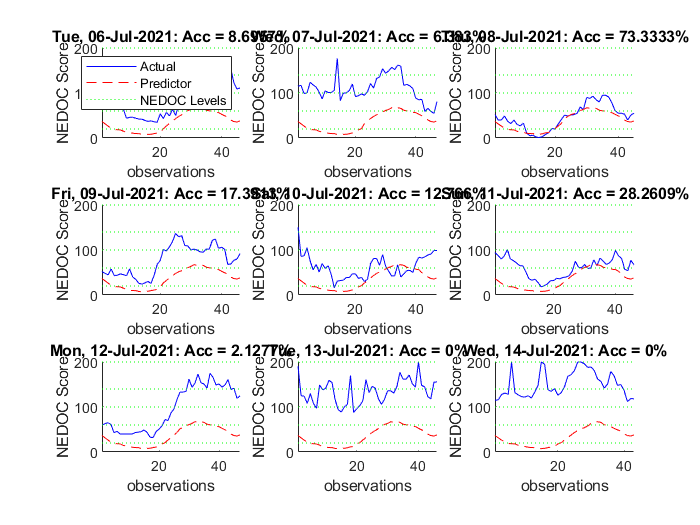

[~,accavg] = data_store.plot('Predictions', 'today', 9, 'TimeFrame', 'days', 'Field', 'imp');

fprintf('\nAverage Accuracy = %.2f%%\n',accavg);


Average Accuracy = 16.55%
